## Tarea 3

### Diseño de VQs para la envolvente espectral 

[s, fs] = audioread('tvg_10minutos_8khz.wav');

p=10;   % orden de predicción

N=160;  % número de muestras
window = ones(1,N); % ventana rectangular
wshift = 160;

[LPC, Ep, RC, LSF, LAR] = speech2lpc(s, p, window, wshift);

% s: señal de voz o sonora.
% p: orden de predicción
% window, wshift: ventana a utilizar y su desplazamiento en muestras.

% Salidas: parámetros correspondientes a cada trama por filas.
% LPC, Ep: LPCs (matriz) y energía del error de predicción (vector).
% RC: coeficientes de reflexión (matriz)
% LSF: Line Spectral Frequencies (matriz)
% LAR: Log Area Ratios (matriz)


epsilon = 0.025;
umbral = 0.001;
display=1;

% Cargamos el .mat
load 'LPCpar.mat'

% NO HAY QUE MOSTARLOS

[VQLPC, vDistLPC] = bsVQ(LPC, 10, epsilon, umbral,display);

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).


[VQRC, vDistRC] = bsVQ(RC, 10, epsilon, umbral,display);
[VQLSF, vDistLSF] = bsVQ(LSF, 10, epsilon, umbral,display);
[VQLAR, vDistLAR] = bsVQ(LAR, 10, epsilon, umbral,display);

save ('VQParametros.mat', 'VQLPC', 'VQRC', 'VQLSF', 'VQLAR');

% Salidas:
% VQ: Matriz con los centroides resultantes por filas. 
% vDist: vector con la evolución de la distorsión en la últimada llamada a
%        Kmeans.
%
% Entradas:
% data : matriz con vector de datos por fila.
% nbits: numero de bits del VQ deseado.
% epsilon: parametro para dividir cada centroide en 2 (ej: 0.025).
% umbral: umbral de parada en GLAvq1
% display: si vale 1 y la dimensión es 2 entonces representa una gráfica.


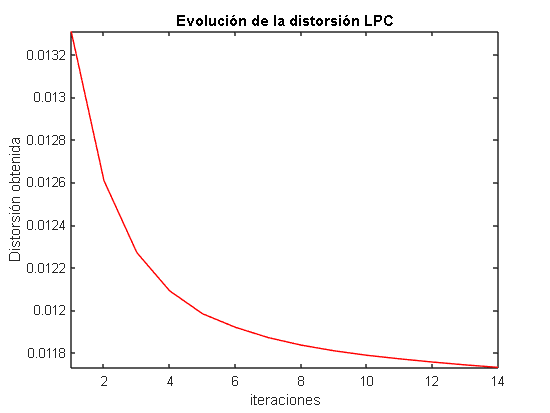

figure(1);
plot(vDistLPC,'r-');
axis tight;
xlabel('iteraciones');
ylabel('Distorsión obtenida');
title('Evolución de la distorsión LPC');

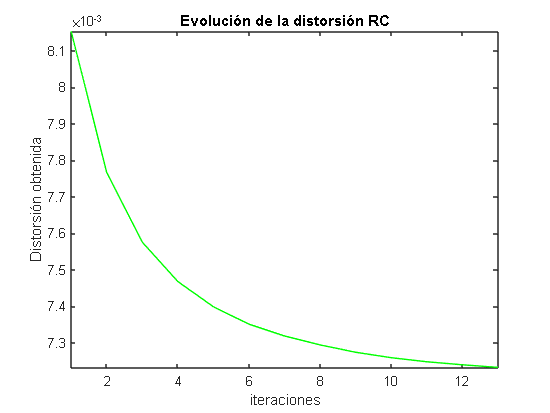

%hold on;
plot(vDistRC,'g-');
axis tight;
xlabel('iteraciones');
ylabel('Distorsión obtenida');
title('Evolución de la distorsión RC');

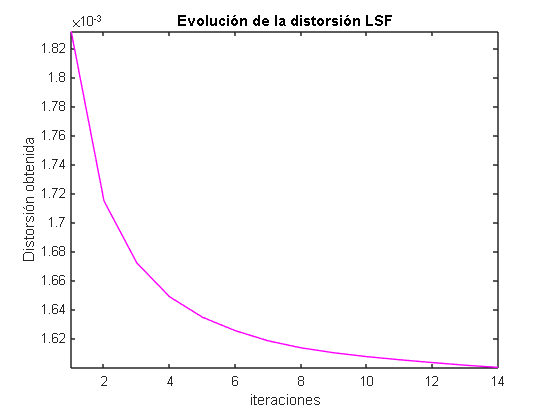

%hold on;
plot(vDistLSF,'m-');
axis tight;
xlabel('iteraciones');
ylabel('Distorsión obtenida');
title('Evolución de la distorsión LSF');

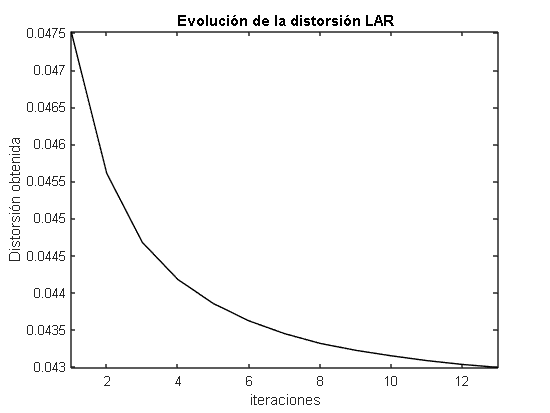

%hold on;
plot(vDistLAR,'k-');
axis tight;
%hold off;
xlabel('iteraciones');
ylabel('Distorsión obtenida');
title('Evolución de la distorsión LAR');